clear all

#### Script MATLAB per Creare i Dati

Centroide: (10.4746, 4.7756)


x_center1 = 10.7844

y_center2 = 4.5655

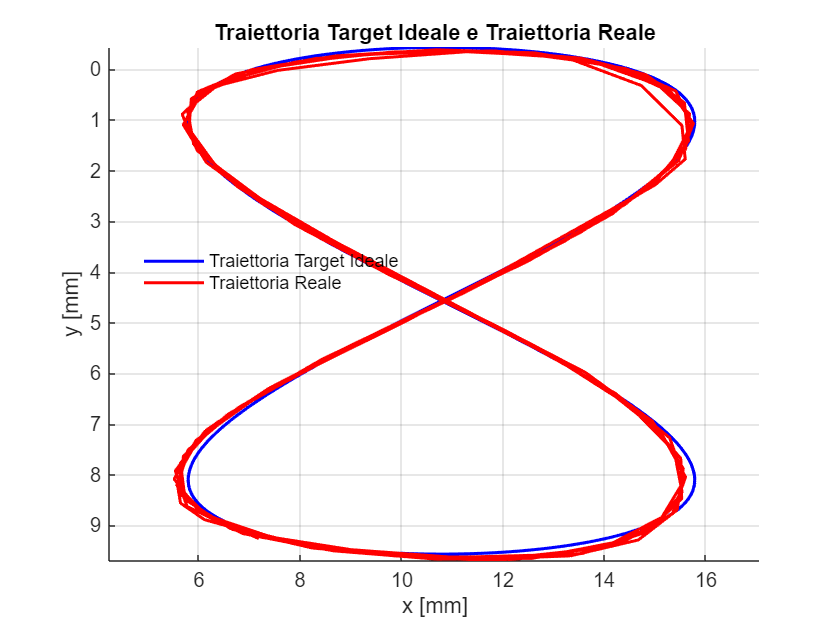

% trajectory = 'otto'; raggio = "r5";  tempo = 't2.5s';
trajectory = 'otto';  tempo = 't_1.256s';
% Percorso base
basePath = fullfile('C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\dati robot3', trajectory);

% Percorso completo del file
fileName = sprintf('laserWorldPoints_filtered.mat');
% fullPath = fullfile(basePath, raggio, tempo, fileName);
fullPath = fullfile(basePath, tempo, fileName);

load([fullPath]);

% ============================================================================================================================================================================
%                                                                               CERCHIO 
% ============================================================================================================================================================================

if strcmp(trajectory, 'cerchio') 

    % Define The Reference Trajectory
    theta = linspace(0, 2*pi, length(laserWorldPoints_filtered(:,2))*5);% Angolo da 0° a 360°
    r = 5; % Raggio in mm
    x_target = r * cos(theta); x_target = x_target';
    y_target = r * sin(theta); y_target = y_target';

    % Visualizzazione
    figure
    plot(x_target, y_target, 'r-', 'LineWidth', 2);
    xlabel('X (mm)');
    ylabel('Y (mm)');
    axis equal;
    title('Target');
    grid on;
    box off
    % L'offset rappresenta la differenza tra il punto di origine della traiettoria target e quello della traiettoria misurata nel sistema di coordinate del mondo
    offset_x = max(laserWorldPoints_filtered(:,1)) - max(x_target);  
    offset_y = max(laserWorldPoints_filtered(:,2)) - max(y_target);

    % Una volta calcolato l'offset, trasla la traiettoria target per allinearla con la traiettoria misurata:
    x_target_aligned = x_target + offset_x;
    y_target_aligned = y_target + offset_y;

    % Ora entrambe le traiettorie si trovano nello stesso sistema di coordinate
    figure
    plot(laserWorldPoints_filtered(:,1), laserWorldPoints_filtered(:,2), 'b-', 'LineWidth', 2); % Traiettoria misurata
    hold on;
    plot(x_target_aligned, y_target_aligned, 'r-', 'LineWidth', 2); % Traiettoria target allineata
    legend('Traiettoria Misurata', 'Traiettoria Target');
    legend box off
    xlabel('X (mm)');
    ylabel('Y (mm)');
    axis equal;
    grid on;
    % set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
    title('Confronto delle Traiettorie Allineate');
    box off

    x_nom = x_target_aligned;                % coordinate x nominali (cioè del target)
    y_nom = y_target_aligned;                % coordinate y nominali (cioè del target)
    x_real = laserWorldPoints_filtered(:,1); % coordinate x della traiettoria del laser
    y_real = laserWorldPoints_filtered(:,2); % coordinate y della traiettoria del laser

end

% ============================================================================================================================================================================
%                                                                               OTTO 
% ============================================================================================================================================================================


if strcmp(trajectory, 'otto')

    x_center = mean(laserWorldPoints_filtered(:,1));
    y_center = mean(laserWorldPoints_filtered(:,2));
    disp(['Centroide: (', num2str(x_center), ', ', num2str(y_center), ')']);
   
    % Parametri da tunare a mano
    initial_roll = x_center+0.31;   % Roll iniziale
    initial_pitch = y_center-0.21;  % Pitch iniziale
    radius = 5;            % Raggio della figura
    % period = 12.56;        % Periodo della figura (secondi)

    % Estrai la parte numerica
    numericPart = regexp(tempo, '\d+\.?\d*', 'match');

    % Converti da stringa (cell array) a double
    period = str2double(numericPart{1});

    % Parametri fissati nel codice CCS
    t_iniziale = 0;         % Tempo iniziale (secondi)
    time_step = 0.01;       % Passo temporale (secondi)
    time_end = 2 * period;  % Durata totale (secondi)

    % Calcolo della traiettoria
    time = t_iniziale:time_step:time_end; % Vettore tempo
    angular_velocity = 2 * pi / period;   % Velocità angolare

    offset_pitch = radius * sin(angular_velocity * time);        % Pitch
    offset_roll = radius * sin(2 * angular_velocity * time);     % Roll

    pitch_trajectory = initial_pitch + offset_pitch; % Traiettoria pitch
    roll_trajectory = initial_roll + offset_roll;    % Traiettoria roll

    x_center1 = mean(roll_trajectory)
    y_center2 = mean(pitch_trajectory)

    figure;
    plot(roll_trajectory, pitch_trajectory, 'b-', 'LineWidth', 1.5);
    hold on;
    plot(laserWorldPoints_filtered(:,1), laserWorldPoints_filtered(:,2), 'r-', 'LineWidth', 1.5);
    xlabel('x [mm]');
    ylabel('y [mm]');
    title('Traiettoria Target Ideale e Traiettoria Reale');
    legend('Traiettoria Target Ideale', 'Traiettoria Reale');
    legend box off
    legend Location best
    grid on;
    hold off;
    grid on;
    axis equal;
    set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
    box off

    x_nom = roll_trajectory';                % coordinate x nominali (cioè del target)
    y_nom = pitch_trajectory';                % coordinate y nominali (cioè del target)
    x_real = laserWorldPoints_filtered(:,1); % coordinate x della traiettoria del laser
    y_real = laserWorldPoints_filtered(:,2); % coordinate y della traiettoria del laser

end

% ============================================================================================================================================================================
%                                                                               ALTRE EVENTUALI TRAIETTORIE 
% ============================================================================================================================================================================


% ============================================================================================================================================================================
% ============================================================================================================================================================================

% Percorso e nome del file
% filePath = fullfile(basePath, raggio, tempo, 'dati.mat');
filePath = fullfile(basePath, tempo, 'dati.mat');

% Salva i dati nel file
save(filePath, 'x_nom', 'y_nom', 'x_real', 'y_real');

#### Script MATLAB per caricare i Dati nel DataSet

% Parametri principali
basePath = 'C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\dati robot'; % Percorso principale
trajectories = {'otto', 'cerchio'};       % Nomi delle traiettorie
dimensions = {'r5', 'r10'};               % Dimensioni
dimensioni = {'Small', 'Big'};
periods = {'t10s', 't5s', 't2.5s'};       % Periodi (in secondi)
periodo = [10, 5, 2.5];

% Inizializza il dataset come tabella vuota
dataset = table();

% Loop per navigare nella directory e caricare i dati
for t = 1:length(trajectories)
    for d = 1:length(dimensions)
        for v = 1:length(periods)
            % Costruisci il percorso al file dati.mat
            filePath = fullfile(basePath, trajectories{t}, dimensions{d}, periods{v}, 'dati.mat');
            
            % Controlla se il file esiste
            if exist(filePath, 'file')
                % Carica i dati
                data = load(filePath);
                
                % Aggiungi una riga al dataset
                newRow = table(trajectories(t), dimensions(d), periods(v), ...
                    {data.x_nom}, {data.y_nom}, {data.x_real}, {data.y_real}, ...
                    'VariableNames', {'Traiettoria', 'Dimensione', 'Periodo', ...
                                      'x_nom', 'y_nom', 'x_real', 'y_real'});
                dataset = [dataset; newRow]; % Aggiungi la nuova riga
            else
                warning('File non trovato: %s', filePath);
            end
        end
    end
end

% Aggiungi una colonna per il RMSE al dataset
dataset.RMSE_t = zeros(height(dataset), 1); % Inizializza con zeri
dataset.STD_t = zeros(height(dataset), 1); % Inizializza con zeri

% Visualizza il dataset
disp(dataset);

    Traiettoria    Dimensione     Periodo          x_nom              y_nom             x_real            y_real        RMSE_t    STD_t
    ___________    __________    _________    _______________    _______________    ______________    ______________    ______    _____

    {'otto'   }     {'r5' }      {'t10s' }    {2001×1 double}    {2001×1 double}    {934×1 double}    {934×1 double}      0         0  
    {'otto'   }     {'r5' }      {'t5s'  }    {1001×1 double}    {1001×1 double}    {526×1 double}    {526×1 double}      0         0  
    {'otto'   }     {'r5' }      {'t2.5s'}    { 501×1 double}    { 501×1 double}    {334×1 double}    {334×1 double}      0         0  
    {'otto'  

#### Calcola RMSE delle traiettorie

for i = 1:height(dataset)

    % Estrai i dati nominali e reali per la riga corrente
    x_nom = dataset.x_nom{i};
    y_nom = dataset.y_nom{i};
    x_real = dataset.x_real{i};
    y_real = dataset.y_real{i};
    
    % Calcola l'errore quadratico medio
    t = (1:1:length(x_real))'/ 25; % per 25 si intende 25Hz del frameRate della camera
    [rmse, rmse_x, rmse_y, std_f, std_x ,std_y, figHandles] = circ_rmse(x_nom, y_nom, x_real ,y_real, t, 0);
    dataset.RMSE_t(i) = rmse;
    dataset.STD_t(i) = std_f;
end

disp(dataset);

    Traiettoria    Dimensione     Periodo          x_nom              y_nom             x_real            y_real        RMSE_t    STD_t 
    ___________    __________    _________    _______________    _______________    ______________    ______________    ______    ______

    {'otto'   }     {'r5' }      {'t10s' }    {2001×1 double}    {2001×1 double}    {934×1 double}    {934×1 double}    99.839    62.398
    {'otto'   }     {'r5' }      {'t5s'  }    {1001×1 double}    {1001×1 double}    {526×1 double}    {526×1 double}    114.86    69.726
    {'otto'   }     {'r5' }      {'t2.5s'}    { 501×1 double}    { 501×1 double}    {334×1 double}    {334×1 double}     142.8    69.671
    {'ot

% Inizializza strutture per le matrici RMSE ed STD
rmse_matrices = struct(); % ogni campo rappresenta una traiettoria
std_matrices = struct();

% Loop per ogni traiettoria
for t = 1:length(trajectories)

    % Inizializza la matrice RMSE ed STD per la traiettoria corrente
    rmse_matrix = zeros(length(dimensions), length(periods));
    std_matrix = zeros(length(dimensions), length(periods));

    % Loop per ogni dimensione
    for d = 1:length(dimensions)

        % Loop per ogni velocità
        for v = 1:length(periods)

            % Filtra il dataset per traiettoria, dimensione e velocità corrente
            filter = strcmp(dataset.Traiettoria, trajectories{t}) & ...
                     strcmp(dataset.Dimensione, dimensions{d}) & ...
                     strcmp(dataset.Periodo, periods{v});
            
            % Estrai il valore di RMSE_t
            if any(filter)

                rmse_value = dataset.RMSE_t(filter); % Valore RMSE
                rmse_matrix(d, v) = rmse_value; % Salva nella matrice

                std_value = dataset.STD_t(filter); % Valore RMSE
                std_matrix(d, v) = std_value; % Salva nella matrice

            else

                rmse_matrix(d, v) = NaN; % Se mancano dati, usa NaN
                std_matrix(d, v) = NaN; % Se mancano dati, usa NaN

            end

        end

    end
    
    % Salva la matrice nel campo della traiettoria
    rmse_matrices.(trajectories{t}) = rmse_matrix;
    std_matrices.(trajectories{t}) = std_matrix;
end

% Visualizza le matrici RMSE per verifica
disp('RMSE Matrices:')

RMSE Matrices:


disp(rmse_matrices);

       otto: [2×3 double]
    cerchio: [2×3 double]



disp('STD Matrices:')

STD Matrices:


disp(std_matrices);

       otto: [2×3 double]
    cerchio: [2×3 double]




% disp('RMSE Matrix for Otto:');
% disp(rmse_matrices.otto); %  matrice dimensions × periodo: prima riga raggio5 prima colonna periodo 10s
% disp('RMSE Matrix for Cerchio:');
% disp(rmse_matrices.cerchio); %  matrice dimensions × periodo: prima riga raggio5 prima colonna periodo 10s

% Matrici dei valori RMSE (estratte dal dataset e calcolate in precedenza)
rmse_cerchio = rmse_matrices.cerchio; % Matrice RMSE per Cerchio
rmse_otto = rmse_matrices.otto;       % Matrice RMSE per Otto

% Matrici dei valori STD (estratte dal dataset e calcolate in precedenza)
std_cerchio = std_matrices.cerchio; % Matrice STD per Cerchio
std_otto = std_matrices.otto;       % Matrice STD per Otto

#### Calcola le VELOCITA' delle traiettorie

% Calcolo della velocità per ciascuna traiettoria
velocity_data = struct();
f_data = struct();

for t = 1:length(trajectories)
    traj_name = trajectories{t};
    velocity_data.(traj_name) = zeros(length(dimensions), length(periods));
    f_data.(traj_name) = zeros(length(dimensions), length(periods));
    for d = 1:length(dimensions)
        % Estrai il raggio dalla dimensione (es. 'r5' -> 5)
        R = str2double(dimensions{d}(2:end)); % Raggio della traiettoria in mm
        for p = 1:length(periods)
            T = periodo(p); % Periodo in secondi
            f = 1 / T;      % Frequenza in Hz
            f_data.(traj_name)(d, p) = f;
            if strcmp(traj_name, 'cerchio')
                velocity_data.(traj_name)(d, p) = 2 * pi * R * f; % mm/s
            elseif strcmp(traj_name, 'otto')
                velocity_data.(traj_name)(d, p) = 4 * pi * R * f; % mm/s
            end
        end
    end
end

#### Plotta i risultati in funzione della frequenza

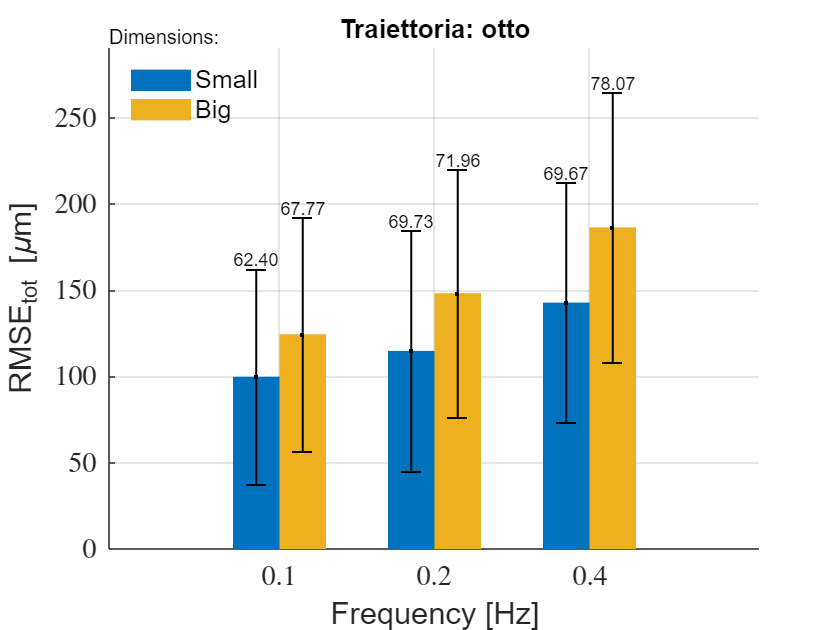

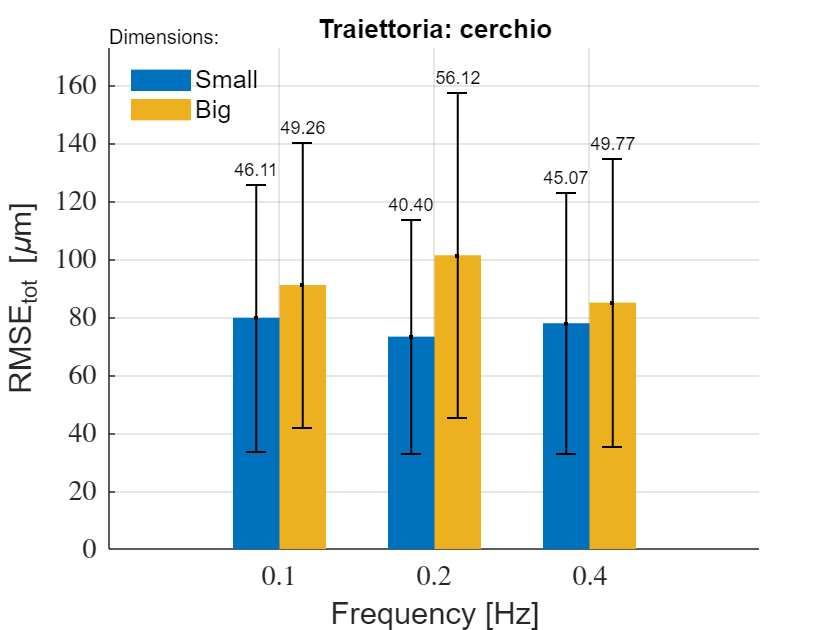

% Loop per creare il grafico per ogni traiettoria
for t = 1:length(trajectories)

    traj_name = trajectories{t};
    velocities = velocity_data.(traj_name);     % Velocità calcolate per la traiettoria corrente
    frequencies = f_data.(traj_name);
    rmse_matrix = rmse_matrices.(traj_name);    % RMSE per la traiettoria corrente
    std_matrix = std_matrices.(traj_name);      % STD per la traiettoria corrente

    % Parametri per il grafico
    num_dimensions = length(dimensions);
    width = 0.3; % Larghezza delle barre
    x = 1:length(periods); % Indici per i periodi
    
    % Creazione del grafico
    figure;

    hold on;
    
     % Array per tenere traccia delle barre (necessario per la legenda)
    hBars = gobjects(num_dimensions, 1);

    for d = 1:num_dimensions
        
        % Posizione delle barre per questa dimensione
        x_pos = x + (d-1) * width;

        % Plot per ogni dimensione
        hBars(d) = bar(x_pos, rmse_matrix(d, :), width, 'DisplayName', dimensioni{d},'Interpreter','tex');
        set(hBars(d), 'EdgeColor', 'none'); % Rimuove i contorni delle barre

        % Aggiunta delle std
        errorbar(x_pos, rmse_matrix(d, :), std_matrix(d, :), ...
                 'k.', 'LineWidth', 1, 'CapSize', 10); % Barre di errore in nero

        % Aggiunta dei valori numerici sopra le barre di errore
        for i = 1:length(x_pos)
            text(x_pos(i), rmse_matrix(d, i) + std_matrix(d, i) + 5, ...
                sprintf('%.2f', std_matrix(d, i)), ... % Valore dell'errore
                'HorizontalAlignment', 'center', 'FontSize', 9, 'Color', 'black','Interpreter','tex');
        end

    end

    % Adattamento dei limiti dell'asse Y
    yMax = max(rmse_matrix(:) + std_matrix(:)); % Valore massimo (RMSE + errore)
    ylim([0, yMax + 0.1 * yMax]); % Margine superiore del 10%
   
    xlabel('Frequency [Hz]', 'FontSize', 12, 'Interpreter', 'tex'); 
    ylabel(sprintf('%s%s [%s]', 'RMSE', '_{tot}', '\mum'), 'FontSize', 12, 'Interpreter', 'tex');

    % Personalizzazione dei valori sull'asse x
    xticks(x + width / 2); % Centrare le etichette delle velocità
    xticklabels(arrayfun(@(v) ['$' sprintf('%.1f', v) '$'], frequencies(1, :), 'UniformOutput', false)); % delimitatori LaTeX $ ... $
    set(gca, 'TickLabelInterpreter', 'latex'); % Usa l'interprete LaTeX
    set(gca, 'FontSize', 14); % Personalizza la dimensione del carattere

    grid on;


    % Aggiungi legenda
    legend(hBars, 'Location', 'northwest'); % Usa l'array delle barre per la legenda
    text(-0.0, 1.02, 'Dimensions:', 'Units', 'normalized', 'FontSize', 10, 'FontWeight','normal','Interpreter','tex');
    legend box off
    
    hold off

    title(['Traiettoria: ', traj_name],'FontSize', 13);
end